cd(fileparts(matlab.desktop.editor.getActiveFilename))
close all; clearvars; clc

load("../../results/trmse_raw.mat")

seq_starts = find(y_within.w_trial==1)+1 % 3 tasks x 2 dof per task = 6 sequences

seq_starts =      2
    11
    20
    29
    38
    47


seq_stops = find(y_within.w_trial==9)+1;
num_subjs = height(y_between);
num_slopes =numel(seq_starts);
param_fit_arr = zeros(num_subjs, num_slopes);
FIT_TYPE = "exponential";
for i=1:num_subjs
    for j=1:num_slopes
        seq = y_between{i, seq_starts(j):seq_stops(j)};
        if FIT_TYPE == "linear"
            [model_fit, lin_gof] = fit((1:9)',seq',"poly1");
            param_fit_arr(i,j) = model_fit.p1;
        elseif FIT_TYPE == "exponential"
            [model_fit, model_gof] = fit((1:9)',seq',"exp1", 'StartPoint', [0.6, -0.2]);
            param_fit_arr(i,j) = model_fit.b;
            % [model_fit, model_gof] = fit((1:9)',seq','log10')
            % param_fit_arr(i,j) = model_fit.a;
        else
            error('Requested fit (%s) is not supported', FIT_TYPE)
        end
    end
end
model_fit

model_fit =      General model Exp1:
     model_fit(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =      0.3017  (0.1077, 0.4957)
       b =     -0.1254  (-0.2806, 0.02973)

m_between = array2table(param_fit_arr);
m_between = [y_between(:,1), m_between]

m_between = 15×7 table
    b_condition    param_fit_arr1    param_fit_arr2    param_fit_arr3    param_fit_arr4    param_fit_arr5    param_fit_arr6
    ___________    ______________    ______________    ______________    ______________    ______________    ______________

      "par"            -0.02729        -0.0011991        -0.0040049         -0.020407         -0.013419        -0.061404   
      "xpar"           0.026332          0.073767          0.021506         -0.042494         -0.030373         -0.14477   
      "par"            0.018484          0.011271          -0.02544           0.10872         -0.012489           -0.215   
      "xpar"          -0.057805         -0.011779          0.019131         -0.026228         -0.050362        -0.0726

m_within = y_within(y_within.w_trial==1,["w_task", "w_gesture"])

m_within = 6×2 table
            w_task                w_gesture    
    ______________________    _________________

    "Machine Learning"        "Co-Activation"  
    "Machine Learning"        "Differentiation"
    "Human Learning"          "Co-Activation"  
    "Human Learning"          "Differentiation"
    "Co-Adaptive Learning"    "Co-Activation"  
    "Co-Adaptive Learning"    "Differentiation"


## Fig Data Prep

fig_data.data = m_between{:,2:end};
fig_data.between = m_between.b_condition;
fig_data.within = m_within{:,"w_task"};

ctrlr_keys = categorical({'Human Learning', 'Machine Learning', 'Co-Adaptive Learning'});
cond_keys = categorical({'paretic', 'nonparetic', 'healthy'});

for i = 1:height(fig_data.between)

    switch fig_data.between(i)
        case "par"
            new_cond_label = cond_keys(1);
        case "xpar"
            new_cond_label = cond_keys(2);
        case "hlt"
            new_cond_label = cond_keys(3);
    end
    fig_data.between(i) = new_cond_label;
end

fig_data.between;
fig_data.data;
for i = 1:numel(ctrlr_keys)
    col_idxs = categorical(fig_data.within) == ctrlr_keys(i);
    for j = 1:numel(cond_keys)
        row_idxs = categorical(fig_data.between) == cond_keys(j);
        cond_vals{j} = reshape(fig_data.data(row_idxs, col_idxs), [],1);
    end
    cond_dict = dictionary(cond_keys, cond_vals);
    ctrlr_vals{i} = cond_dict;
end
ctrlr_dict = dictionary(ctrlr_keys, ctrlr_vals);

## Fig Data Mean +/- SEM

N = length(ctrlr_dict{"Co-Adaptive Learning"}{"paretic"})

N = 10

learning_rate_mean = [
    mean(ctrlr_dict{"Human Learning"}{"paretic"}), mean(ctrlr_dict{"Human Learning"}{"nonparetic"}), mean(ctrlr_dict{"Human Learning"}{"healthy"});
    mean(ctrlr_dict{"Machine Learning"}{"paretic"}), mean(ctrlr_dict{"Machine Learning"}{"nonparetic"}), mean(ctrlr_dict{"Machine Learning"}{"healthy"});
    mean(ctrlr_dict{"Co-Adaptive Learning"}{"paretic"}), mean(ctrlr_dict{"Co-Adaptive Learning"}{"nonparetic"}), mean(ctrlr_dict{"Co-Adaptive Learning"}{"healthy"})
    ]

learning_rate_mean =     0.0225    0.0088   -0.0050
   -0.0442   -0.0372   -0.0504
   -0.0797   -0.0623   -0.0983


learning_rate_sem = [
    std(ctrlr_dict{"Human Learning"}{"paretic"}), std(ctrlr_dict{"Human Learning"}{"nonparetic"}), std(ctrlr_dict{"Human Learning"}{"healthy"});
    std(ctrlr_dict{"Machine Learning"}{"paretic"}), std(ctrlr_dict{"Machine Learning"}{"nonparetic"}), std(ctrlr_dict{"Machine Learning"}{"healthy"});
    std(ctrlr_dict{"Co-Adaptive Learning"}{"paretic"}), std(ctrlr_dict{"Co-Adaptive Learning"}{"nonparetic"}), std(ctrlr_dict{"Co-Adaptive Learning"}{"healthy"})
    ]/sqrt(N)

learning_rate_sem =     0.0163    0.0141    0.0100
    0.0220    0.0242    0.0121
    0.0240    0.0133    0.0241


error_plus = learning_rate_sem;
error_minus = error_plus

error_minus =     0.0163    0.0141    0.0100
    0.0220    0.0242    0.0121
    0.0240    0.0133    0.0241


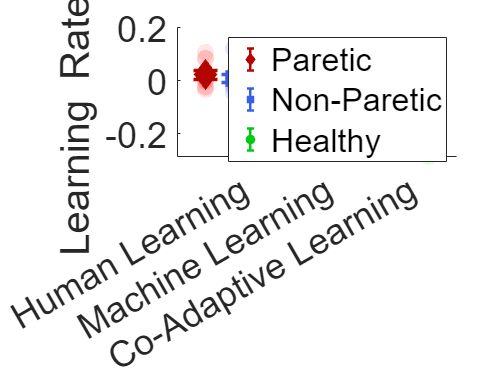

fig_h = figure;
mk_size = 200;
mk_size_err = 15;
ln_width = 3;
mk_alpha = 0.10;
cap_size = 20;
color_scheme = {[179,6,0]/255, [55,96,227]/255, [0,201,20]/255};
hold on
scatter(1*ones(N,1), ctrlr_dict{"Human Learning"}{"paretic"}, mk_size, 'red', 'filled', 'MarkerFaceAlpha', mk_alpha)
scatter(2*ones(N,1), ctrlr_dict{"Human Learning"}{"nonparetic"}, mk_size, 'blue', 'filled', 'MarkerFaceAlpha', mk_alpha)
scatter(3*ones(N,1), ctrlr_dict{"Human Learning"}{"healthy"}, mk_size, 'green', 'filled', 'MarkerFaceAlpha', mk_alpha)
scatter(4*ones(N,1), ctrlr_dict{"Machine Learning"}{"paretic"}, mk_size, 'red', 'filled', 'MarkerFaceAlpha', mk_alpha)
scatter(5*ones(N,1), ctrlr_dict{"Machine Learning"}{"nonparetic"}, mk_size, 'blue', 'filled', 'MarkerFaceAlpha', mk_alpha)
scatter(6*ones(N,1), ctrlr_dict{"Machine Learning"}{"healthy"}, mk_size, 'green', 'filled', 'MarkerFaceAlpha', mk_alpha)
scatter(7*ones(N,1), ctrlr_dict{"Co-Adaptive Learning"}{"paretic"}, mk_size, 'red', 'filled', 'MarkerFaceAlpha', mk_alpha)
scatter(8*ones(N,1), ctrlr_dict{"Co-Adaptive Learning"}{"nonparetic"}, mk_size, 'blue', 'filled', 'MarkerFaceAlpha', mk_alpha)
scatter(9*ones(N,1), ctrlr_dict{"Co-Adaptive Learning"}{"healthy"}, mk_size, 'green', 'filled', 'MarkerFaceAlpha', mk_alpha)
plt_h(3) = errorbar((3:3:9)', ...
           [mean(ctrlr_dict{"Human Learning"}{"healthy"}); mean(ctrlr_dict{"Machine Learning"}{"healthy"}); mean(ctrlr_dict{"Co-Adaptive Learning"}{"healthy"})], ...
           [std(ctrlr_dict{"Human Learning"}{"healthy"}); std(ctrlr_dict{"Machine Learning"}{"healthy"}); std(ctrlr_dict{"Co-Adaptive Learning"}{"healthy"})]/sqrt(N), ...
           'o', 'LineWidth', ln_width, 'MarkerSize', mk_size_err, 'Color', color_scheme{3}, 'MarkerFaceColor', color_scheme{3}, 'CapSize', cap_size);
plt_h(2) = errorbar((2:3:9)', ...
           [mean(ctrlr_dict{"Human Learning"}{"nonparetic"}); mean(ctrlr_dict{"Machine Learning"}{"nonparetic"}); mean(ctrlr_dict{"Co-Adaptive Learning"}{"nonparetic"})], ...
           [std(ctrlr_dict{"Human Learning"}{"nonparetic"}); std(ctrlr_dict{"Machine Learning"}{"nonparetic"}); std(ctrlr_dict{"Co-Adaptive Learning"}{"nonparetic"})]/sqrt(N), ...
           's', 'LineWidth', ln_width, 'MarkerSize', mk_size_err, 'Color', color_scheme{2}, 'MarkerFaceColor', color_scheme{2}, 'CapSize', cap_size);
plt_h(1) = errorbar( (1:3:9)', ...
           [mean(ctrlr_dict{"Human Learning"}{"paretic"}); mean(ctrlr_dict{"Machine Learning"}{"paretic"}); mean(ctrlr_dict{"Co-Adaptive Learning"}{"paretic"})], ...
           [std(ctrlr_dict{"Human Learning"}{"paretic"}); std(ctrlr_dict{"Machine Learning"}{"paretic"}); std(ctrlr_dict{"Co-Adaptive Learning"}{"paretic"})]/sqrt(N), ...
           'd', 'LineWidth', ln_width, 'MarkerSize', mk_size_err, 'Color', color_scheme{1}, 'MarkerFaceColor', color_scheme{1}, 'CapSize', cap_size);
hold off
xlim([0,10])
xticks(2:3:9)
xticklabels(["Human Learning", "Machine Learning", "Co-Adaptive Learning"])
fontsize(fig_h, 30,"points")
legend(plt_h, "Paretic", "Non-Paretic", "Healthy")
ylabel("Learning Rate (\lambda)")

[ctrlr_dict, ctrlr_keys, cond_keys] = table_to_dict(m_between, m_within)

ctrlr_dict =   dictionary (categorical ⟼ cell) with 3 entries:

    Human Learning       ⟼ {[dictionary (categorical ⟼ cell) with 3 entries]}
    Machine Learning     ⟼ {[dictionary (categorical ⟼ cell) with 3 entries]}
    Co-Adaptive Learning ⟼ {[dictionary (categorical ⟼ cell) with 3 entries]}


ctrlr_keys = 1×3 categorical array
     Human Learning      Machine Learning      Co-Adaptive Learning 


cond_keys = 1×3 categorical array
     paretic      nonparetic      healthy 


[data_mean, data_sem, N] = compute_inf_stats(ctrlr_dict)

data_mean =     0.0225    0.0088   -0.0050
   -0.0442   -0.0372   -0.0504
   -0.0797   -0.0623   -0.0983


data_sem =     0.0163    0.0141    0.0100
    0.0220    0.0242    0.0121
    0.0240    0.0133    0.0241


N = 10

tlo = tiledlayout('flow');
fontsize(tlo, 20, "points")
% tlo.Units = 'inches';
% tlo.OuterPosition = [0 0 17 10.5];
ax_handle_list = [];
for cond = ["par", "xpar", "hlt"]
    y_cond = m_between(m_between.b_condition==cond,2:end);
    for task = ["Machine Learning", "Human Learning", "Co-Adaptive Learning"]
        y_coact = y_cond(:, and(m_within.w_task == task, m_within.w_gesture == "Co-Activation"));
        y_diffact = y_cond(:, and(m_within.w_task == task, m_within.w_gesture == "Differentiation"));
        ax_handle = nexttile;
        ax_handle_list = [ax_handle_list, ax_handle];
        hold on
        boxchart([y_coact{:,:};y_diffact{:,:}])
        scatter(ones(size(y_coact)), y_coact{:,:}, 175, 'o', 'MarkerFaceColor','k', 'MarkerEdgeColor','none', 'MarkerFaceAlpha',0.3)
        scatter(ones(size(y_diffact)), y_diffact{:,:}, 175, 'v', 'MarkerFaceColor',"#8c8c8c", 'MarkerEdgeColor', 'none','MarkerFaceAlpha',0.25)
        hold off
        title(task)
        switch task
            case "Machine Learning"
                title(task, 'Color', "#f0a150")
            case "Human Learning"
                title(task, 'Color', "#c76706")
            case "Co-Adaptive Learning"
                title(task, 'Color', "#f48020")
        end
        switch cond
            case "par"
                subtitle("Paretic", 'Color', "#b30600")
            case "xpar"
                subtitle("Nonparetic", 'Color', "#3760e3")
            case "hlt"
                subtitle("Healthy", 'Color', "#29af34")
        end
        % xticks(1:9)
        % yticks(-0.05:0.025:0.05)
    end
end
legend_handle = legend(["Co-Activation (Power)", "", "", "Differential Activation (Tripod)"], "Location","eastoutside");

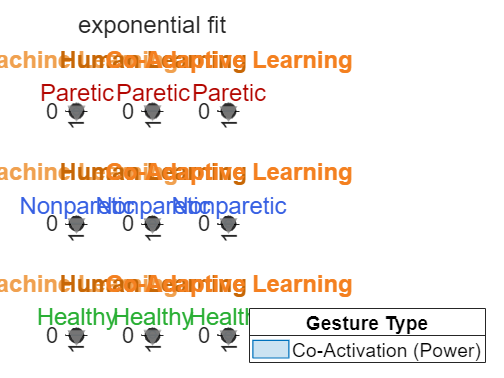

title(legend_handle, "Gesture Type")
linkaxes(ax_handle_list, 'xy')
ylim(1.1*[min(param_fit_arr,[], 'all'), max(param_fit_arr,[], 'all')])
% xlim([0 2])
% title(tlo, sprintf("%s Vs. Trial Count", upper(metric_type)))
set(ax_handle_list, 'FontSize', 18)
title(tlo, sprintf("%s fit", FIT_TYPE))

[ctrlr_dict, ctrlr_keys, cond_keys] = table_to_dict(m_between, m_within);
[data_mean, data_sem, N] = compute_inf_stats(ctrlr_dict)

data_mean =     0.0225    0.0088   -0.0050
   -0.0442   -0.0372   -0.0504
   -0.0797   -0.0623   -0.0983


data_sem =     0.0163    0.0141    0.0100
    0.0220    0.0242    0.0121
    0.0240    0.0133    0.0241


N = 10

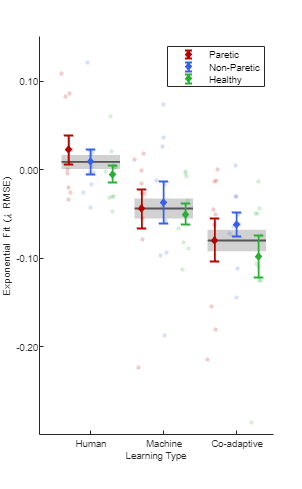

fig_h = figure;
set(fig_h, 'Renderer', 'painters');
set(fig_h, "Units","centimeters", "Position", [15, 5, 8.89, 14.38])
cap_size = 8;
color_names = ["red", "blue", "green", "gray", "black"];
color_vals = {[179,6,0]/255, [55,96,227]/255, [41,175,52]/255, [153,153,153]/255, [26,26,26]/255};
color_scheme = dictionary(color_names, color_vals);
mk_alpha = 0.20;
mk_size = 12;
mk_size_err = 4;
ln_width = 1.5;
xj_width = 0.5;
sem_factor = 1;

hold on
x_locs = [1.00,1.75,2.50,3.50,4.25,5.00,6.00,6.75,7.50];

patch_opts = {'FaceColor', color_scheme{"gray"}, 'EdgeColor', 'none', 'FaceAlpha', 0.45};
group_x_offset = 0.25;
group_x = [x_locs(1)-group_x_offset, x_locs(3)+group_x_offset];
group_mean = ones(size(group_x))*mean([ctrlr_dict{"Human Learning"}{"paretic"};ctrlr_dict{"Human Learning"}{"nonparetic"}; ctrlr_dict{"Human Learning"}{"healthy"}]);
group_sem = ones(size(group_x))*std([ctrlr_dict{"Human Learning"}{"paretic"};ctrlr_dict{"Human Learning"}{"nonparetic"}; ctrlr_dict{"Human Learning"}{"healthy"}])/sqrt(3*N)*sem_factor;
plot(group_x, group_mean, 'LineWidth', ln_width, 'Color', color_scheme{"black"})
patch_x = [group_x, fliplr(group_x)];
patch_y = [group_mean+group_sem, fliplr(group_mean-group_sem)];
patch(patch_x, patch_y, 1, patch_opts{:});

group_x = [x_locs(4)-group_x_offset, x_locs(6)+group_x_offset];
group_mean = ones(size(group_x))*mean([ctrlr_dict{"Machine Learning"}{"paretic"};ctrlr_dict{"Machine Learning"}{"nonparetic"}; ctrlr_dict{"Machine Learning"}{"healthy"}]);
group_sem = ones(size(group_x))*std([ctrlr_dict{"Machine Learning"}{"paretic"};ctrlr_dict{"Machine Learning"}{"nonparetic"}; ctrlr_dict{"Machine Learning"}{"healthy"}])/sqrt(3*N)*sem_factor;
plot(group_x, group_mean, 'LineWidth', ln_width, 'Color', color_scheme{"black"})
patch_x = [group_x, fliplr(group_x)];
patch_y = [group_mean+group_sem, fliplr(group_mean-group_sem)];
patch(patch_x, patch_y, 1, patch_opts{:});

group_x = [x_locs(7)-group_x_offset, x_locs(9)+group_x_offset];
group_mean = ones(size(group_x))*mean([ctrlr_dict{"Co-Adaptive Learning"}{"paretic"};ctrlr_dict{"Co-Adaptive Learning"}{"nonparetic"}; ctrlr_dict{"Co-Adaptive Learning"}{"healthy"}]);
group_sem = ones(size(group_x))*std([ctrlr_dict{"Co-Adaptive Learning"}{"paretic"};ctrlr_dict{"Co-Adaptive Learning"}{"nonparetic"}; ctrlr_dict{"Co-Adaptive Learning"}{"healthy"}])/sqrt(3*N)*sem_factor;
plot(group_x, group_mean, 'LineWidth', ln_width, 'Color', color_scheme{"black"})
patch_x = [group_x, fliplr(group_x)];
patch_y = [group_mean+group_sem, fliplr(group_mean-group_sem)];
patch(patch_x, patch_y, 1, patch_opts{:});

swarm_opts = {'filled', 'MarkerFaceAlpha', mk_alpha, 'XJitter', 'randn', 'XJitterWidth', xj_width};
swarmchart(x_locs(1)*ones(N,1), ctrlr_dict{"Human Learning"}{"paretic"}, mk_size, color_scheme{"red"}, swarm_opts{:})
swarmchart(x_locs(2)*ones(N,1), ctrlr_dict{"Human Learning"}{"nonparetic"}, mk_size, color_scheme{"blue"}, swarm_opts{:})
swarmchart(x_locs(3)*ones(N,1), ctrlr_dict{"Human Learning"}{"healthy"}, mk_size, color_scheme{"green"}, swarm_opts{:})

swarmchart(x_locs(4)*ones(N,1), ctrlr_dict{"Machine Learning"}{"paretic"}, mk_size, color_scheme{"red"}, swarm_opts{:})
swarmchart(x_locs(5)*ones(N,1), ctrlr_dict{"Machine Learning"}{"nonparetic"}, mk_size, color_scheme{"blue"}, swarm_opts{:})
swarmchart(x_locs(6)*ones(N,1), ctrlr_dict{"Machine Learning"}{"healthy"}, mk_size, color_scheme{"green"}, swarm_opts{:})

swarmchart(x_locs(7)*ones(N,1), ctrlr_dict{"Co-Adaptive Learning"}{"paretic"}, mk_size, color_scheme{"red"}, swarm_opts{:})
swarmchart(x_locs(8)*ones(N,1), ctrlr_dict{"Co-Adaptive Learning"}{"nonparetic"}, mk_size, color_scheme{"blue"}, swarm_opts{:})
swarmchart(x_locs(9)*ones(N,1), ctrlr_dict{"Co-Adaptive Learning"}{"healthy"}, mk_size, color_scheme{"green"}, swarm_opts{:})

ebar_opts = {'LineStyle', 'none', 'LineWidth', ln_width, 'Marker', 'd', 'MarkerSize', mk_size_err, 'CapSize', cap_size};
plt_h(1) = errorbar(x_locs(1:3:9)', ...
           [mean(ctrlr_dict{"Human Learning"}{"paretic"}); mean(ctrlr_dict{"Machine Learning"}{"paretic"}); mean(ctrlr_dict{"Co-Adaptive Learning"}{"paretic"})], ...
           [std(ctrlr_dict{"Human Learning"}{"paretic"}); std(ctrlr_dict{"Machine Learning"}{"paretic"}); std(ctrlr_dict{"Co-Adaptive Learning"}{"paretic"})]/sqrt(N), ...
           ebar_opts{:}, 'Color', color_scheme{"red"}, 'MarkerFaceColor', color_scheme{"red"});
plt_h(2) = errorbar(x_locs(2:3:9)', ...
           [mean(ctrlr_dict{"Human Learning"}{"nonparetic"}); mean(ctrlr_dict{"Machine Learning"}{"nonparetic"}); mean(ctrlr_dict{"Co-Adaptive Learning"}{"nonparetic"})], ...
           [std(ctrlr_dict{"Human Learning"}{"nonparetic"}); std(ctrlr_dict{"Machine Learning"}{"nonparetic"}); std(ctrlr_dict{"Co-Adaptive Learning"}{"nonparetic"})]/sqrt(N), ...
           ebar_opts{:}, 'Color', color_scheme{"blue"}, 'MarkerFaceColor', color_scheme{"blue"});
plt_h(3) = errorbar(x_locs(3:3:9)', ...
           [mean(ctrlr_dict{"Human Learning"}{"healthy"}); mean(ctrlr_dict{"Machine Learning"}{"healthy"}); mean(ctrlr_dict{"Co-Adaptive Learning"}{"healthy"})], ...
           [std(ctrlr_dict{"Human Learning"}{"healthy"}); std(ctrlr_dict{"Machine Learning"}{"healthy"}); std(ctrlr_dict{"Co-Adaptive Learning"}{"healthy"})]/sqrt(N), ...
           ebar_opts{:}, 'Color', color_scheme{"green"}, 'MarkerFaceColor', color_scheme{"green"});
hold off

% xlim([0,10])
xlabel("Learning Type")
xticks(x_locs(2:3:9))
xticklabels(["Human", "Machine", "Co-adaptive"])
ylabel("Exponential Fit (\lambda RMSE)")
yticks(-0.20:0.10:0.20)
ytickformat('%0.2f')
legend(plt_h, "Paretic", "Non-Paretic", "Healthy")
fontsize(fig_h, 8,"points")

% title("Learning Rate")

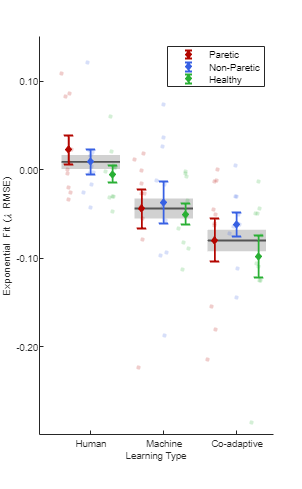

print(fig_h, '../../results/eps-figs/eta-rmse', '-depsc', '-r600', '-vector')

figure
raincloud_data = [
    [ctrlr_dict{"Human Learning"}{"paretic"};ctrlr_dict{"Human Learning"}{"nonparetic"};ctrlr_dict{"Human Learning"}{"healthy"}],...
    [ctrlr_dict{"Machine Learning"}{"paretic"};ctrlr_dict{"Machine Learning"}{"nonparetic"};ctrlr_dict{"Machine Learning"}{"healthy"}],...
    [ctrlr_dict{"Co-Adaptive Learning"}{"paretic"};ctrlr_dict{"Co-Adaptive Learning"}{"nonparetic"};ctrlr_dict{"Co-Adaptive Learning"}{"healthy"}]
]

raincloud_data =    -0.0040   -0.0273   -0.0134
   -0.0254    0.0185   -0.0125
    0.0078   -0.0790   -0.0511
   -0.0338   -0.0153   -0.0633
    0.0225   -0.0270   -0.0001
   -0.0204   -0.0012   -0.0614
    0.1087    0.0113   -0.2150
    0.0827   -0.2234   -0.1543
    0.0005   -0.0433   -0.0452
    0.0859   -0.0558   -0.1811


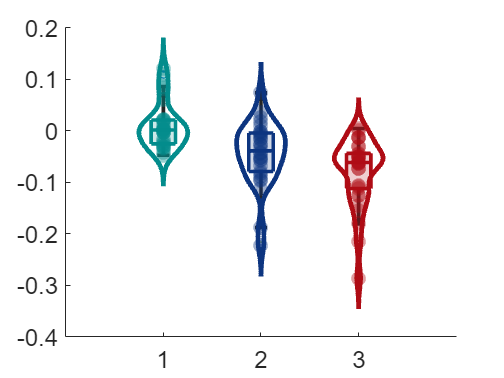

ans =   Figure (27) with properties:

      Number: 27
        Name: ''
       Color: [1 1 1]
    Position: [680 458 560 420]
       Units: 'pixels'

  Show all properties


frm_dviz_utils.plot_rainclouds(raincloud_data, 'quadruple', 'vase', 0.02)

### Export to R

r_dataframe = [];
for i=1:height(m_between)
    if or(m_between{i,1} == "par", m_between{i,1} == "xpar")
        p_id = i+mod(i,2);
    else
        p_id = i;
    end
    p_tbl = array2table([m_between{i,2:end}', repmat(sprintf("p%02d",p_id), height(m_within),1), repmat(m_between{i,1}, height(m_within),1), m_within{:,:}], ...
        "VariableNames", ["rmse", "p_id", "p_cond", "task_type", "gesture_type"]);
    r_dataframe = [r_dataframe; p_tbl];
end

r_dataframe = convertvars(r_dataframe, ["rmse"], 'double');
r_dataframe = convertvars(r_dataframe, ["gesture_type", "task_type", "p_cond", "p_id"], 'categorical');
r_dataframe = r_dataframe(:,{'rmse' 'gesture_type' 'task_type' 'p_cond', 'p_id'})

r_dataframe = 90×5 table
       rmse        gesture_type           task_type          p_cond    p_id
    __________    _______________    ____________________    ______    ____

      -0.02729    Co-Activation      Machine Learning         par      p02 
    -0.0011991    Differentiation    Machine Learning         par      p02 
    -0.0040049    Co-Activation      Human Learning           par      p02 
     -0.020407    Differentiation    Human Learning           par      p02 
     -0.013419    Co-Activation      Co-Adaptive Learning     par      p02 
     -0.061404    Differentiation    Co-Adaptive Learning     par      p02 
      0.026332    Co-Activation      Machine Learning         xpar     p02 
      0.073767    Differentiation    Machine Learning         xpar     p02 
      0.021506    Co-Activation      Human L

writetable(r_dataframe, '../../temp-data/rdf_rmse_slope_10.csv','WriteMode','overwrite')

### 2-Way ANOVA

disp(FIT_TYPE)

exponential


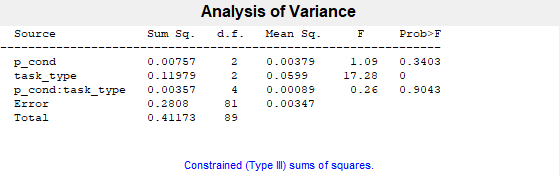

[pvals,anova_tbl,stats, terms] = anovan(r_dataframe{:,"rmse"}, ...
    {r_dataframe{:,"p_cond"}, r_dataframe{:,"task_type"}}, ...
    'varnames',["p_cond", "task_type"], ...
    'model',2);

pvals

pvals =     0.3403
    0.0000
    0.9043


terms = terms(2,:)

terms =      0     1


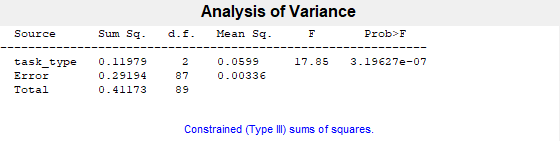

[pvals,anova_tbl,stats, terms] = anovan(r_dataframe{:,"rmse"}, ...
    {r_dataframe{:,"p_cond"}, r_dataframe{:,"task_type"}}, ...
    'varnames',["p_cond", "task_type"], ...
    'model',terms);

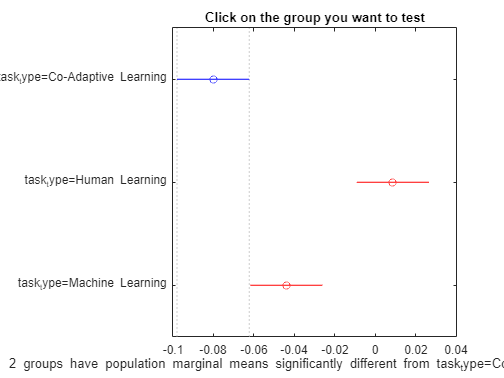

results =     1.0000    2.0000   -0.1245   -0.0889   -0.0532    0.0000
    1.0000    3.0000   -0.0718   -0.0362   -0.0005    0.0460
    2.0000    3.0000    0.0170    0.0527    0.0883    0.0020


estimates =    -0.0801    0.0106
    0.0087    0.0106
   -0.0439    0.0106


group_names = 3×1 cell array
    {'task_type=Co-Adaptive Learning'}
    {'task_type=Human Learning'      }
    {'task_type=Machine Learning'    }


figure
[results, estimates, ~, group_names] = multcompare(stats, "Dimension",[2])

format short
tbl = array2table(results,"VariableNames", ...
    ["Group","Control Group","Lower Limit","Difference","Upper Limit","P-value"]);
tbl.("Group") = group_names(tbl.("Group"));
tbl.("Control Group") = group_names(tbl.("Control Group"))

tbl = 3×6 table
                  Group                           Control Group             Lower Limit    Difference    Upper Limit     P-value  
    __________________________________    ______________________________    ___________    __________    ___________    __________

    {'task_type=Co-Adaptive Learning'}    {'task_type=Human Learning'  }     -0.12452      -0.088855       -0.053191    1.7061e-07
    {'task_type=Co-Adaptive Learning'}    {'task_type=Machine Learning'}     -0.07184      -0.036175     -0.00051089      0.046033
    {'task_type=Human Learning'      }    {'task_type=Machine Learning'}     0.017015        0.05268        0.088344     0.0019609


estimates

estimates =    -0.0801    0.0106
    0.0087    0.0106
   -0.0439    0.0106
